clc; clear; close all; addpath z_toolbox;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'EDas', 'IEDtwDas', 'adjR2_twDED_as');
[~, order_opt] = max(mean(adjR2_twDED_as, 1));
disp(order_opt);

     6



[forest, tf, scores] = iforest([EDas, IEDtwDas], "ContaminationFraction", 0.1);
EDas = EDas(scores <= forest.ScoreThreshold);
IEDtwDas = IEDtwDas(scores <= forest.ScoreThreshold);
[polyModel, Curve, Ftest] = f_polyfit(EDas, IEDtwDas, order_opt);
disp(polyModel.adjR2);

    0.1297



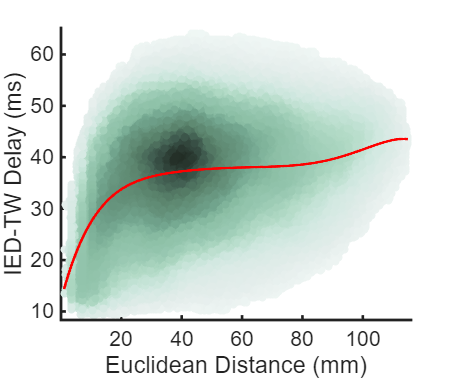

figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
f_densityScatter(EDas, IEDtwDas, 1); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(EDas)-1, max(EDas)+1]); ylim([min(IEDtwDas)-1, max(IEDtwDas)+1]);
xlabel('Euclidean Distance (mm)'); ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

clc; clear; close all; addpath E:\IEDpropagation\z_toolbox;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'adjR2_twDED_as'); 
[~, order_opt] = max(mean(adjR2_twDED_as, 1));
adjR2_twDED_as_true = adjR2_twDED_as(:, order_opt);
disp(order_opt);

     6



disp(mean(adjR2_twDED_as_true));

    0.1146



disp(std(adjR2_twDED_as_true));

    0.0117



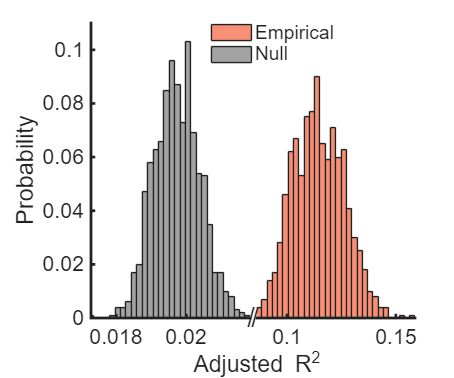

load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), ...
    'adjR2_twDED_as');
adjR2_twDED_as_null = adjR2_twDED_as(:, order_opt, :);
adjR2_twDED_as_null = squeeze(mean(adjR2_twDED_as_null, 1));
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
Ax1 = axes; set(Ax1, 'Position', [0.2, 0.16, 0.35, 0.78]);
histogram(adjR2_twDED_as_null(:), 30, 'FaceColor', [0.4, 0.4, 0.4], ...
    'Normalization', 'probability');
xlim([min(adjR2_twDED_as_null(:)), max(adjR2_twDED_as_null(:))]); 
ylim([0, 0.11]); 
xlabel('Adjusted R^2', 'Position', [0.022, -0.011]);  ylabel('Probability');
annotation('textbox', [0.502, 0.105, 0.1, 0.1], 'String', '/', ...
           'EdgeColor', 'none', 'FontSize', 20, ...
           'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
annotation('textbox', [0.511, 0.105, 0.1, 0.1], 'String', '/', ...
           'EdgeColor', 'none', 'FontSize', 20, ...
           'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
set(Ax1, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
Ax2 = axes; set(Ax2, 'Position', [0.565, 0.16, 0.35, 0.78]);
histogram(adjR2_twDED_as_true(:), 30, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability'); hold on;
histogram(adjR2_twDED_as_null(:), 30, 'FaceColor', [0.4, 0.4, 0.4], ...
    'Normalization', 'probability'); hold off;
xlim([min(adjR2_twDED_as_true(:)), max(adjR2_twDED_as_true(:))]); 
ylim([0, 0.11]);
legend(["Empirical", "Null"], "Box", "off", "Position", [0.4577 0.8239 0.2863, 0.1230]);
set(Ax2, 'YColor', 'none', 'ytick', [], 'yticklabel', [], ...
    'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = adjR2_twDED_as_true(:); y = adjR2_twDED_as_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ' num2str(df)]);

p = 0 z = 38.7201 Cliff Delta = 1 df = 1998


clc; clear; close all; addpath(fullfile('z_toolbox', 'Violinplot'));
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), 'adjR2_twDED');
[~, order_opt] = max(mean(adjR2_twDED, 1));
disp(order_opt)

     6



adjR2_twDED_true = mean(adjR2_twDED(:, order_opt), 2);
disp(mean(adjR2_twDED_true));

    0.2302



disp(std(adjR2_twDED_true));

    0.1177



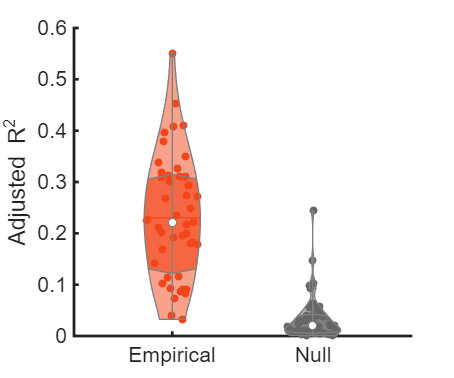

trueStr = cell(length(adjR2_twDED_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), 'adjR2_twDED');
adjR2_twDED_as_null = mean(mean(adjR2_twDED(:, 4:6, :), 3), 2);
nullStr = cell(length(adjR2_twDED_as_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
adjR2 = [adjR2_twDED_true; adjR2_twDED_as_null];
Origin = [trueStr; nullStr];
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
vs = violinplot(adjR2, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); ylabel('Adjusted R^2');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = adjR2_twDED_true(:); y = adjR2_twDED_as_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 1.382e-14 z = 7.698 Cliff Delta = 0.92214 df = 92
